N = 500; rho = 0.3;                                   % Particles, density
sigma = 1; R = sigma; epsilon = 1;                    % Cutoff distance, cutoff (particle radius), well depth
L = (N/rho)^(1/3); Lred = L/sigma;                    % length and reduced length
T = 0.9; iterations = 5000;                            % Setting iterations as 100 times for now    
global B; B = 1/(T*epsilon);
% The following arguments are for Gaussian Moves
move_num = 1;           % Set as either 1 or N for one particle or all particle movement
sig = Lred/6;           % Set the standard deviation of the Gaussian distribution

## Run with Linear Distribution

[pos_hist, P_hist, vir_hist, U_hist, eff] = MC_Project_Pipeline(N, R, Lred, sigma, epsilon, iterations, rho);

    "run number is "    "500"

    "run number is "    "1000"

    "run number is "    "1500"

    "run number is "    "2000"

    "run number is "    "2500"

    "run number is "    "3000"

    "run number is "    "3500"

    "run number is "    "4000"

    "run number is "    "4500"

    "run number is "    "5000"



## To Run with Gaussian Moves

[pos_histG, P_histG, vir_histG, U_histG, effG] = MC_Project_Pipeline_Gaussian(N, R, Lred, sigma, epsilon, iterations, rho, move_num, sig)

    "run number is "    "500"

    "run number is "    "1000"

    "run number is "    "1500"

    "run number is "    "2000"

    "run number is "    "2500"

    "run number is "    "3000"

    "run number is "    "3500"

    "run number is "    "4000"

    "run number is "    "4500"

    "run number is "    "5000"



pos_histG =     1.1726    1.4678    0.5909
    1.4041    0.2182    0.6225
    2.0821    0.7609    1.5650
    2.6590    2.4914    1.7355
   -0.3326   -0.2191    2.6861
    1.2296    1.9783    2.2830
    1.8799    2.4537   -0.3267
    2.4288    0.5519    0.5979
    2.6581    1.4615    2.3606
    0.4492    2.6660    0.7747


P_histG =     0.2445
    0.2445
    0.2937
    0.0696
    0.0696
    0.0696
    0.0696
    0.0778
    0.1207
    0.1207


vir_histG =    -0.8495
   -0.8495
    0.7885
   -6.6789
   -6.6789
   -6.6789
   -6.6789
   -6.4060
   -4.9779
   -4.9779


U_histG =   -12.3585
  -12.3585
  -11.2902
  -11.5421
  -11.5421
  -11.5421
  -11.5421
  -11.8336
  -12.2668
  -12.2668


effG = 1083

## Plotting

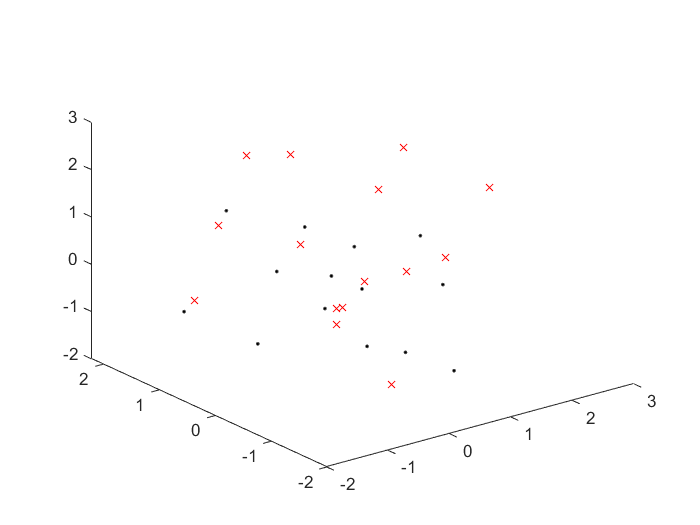

% Will plot the scatterplot of the initial and final positions, as well as
% give an energy over time graph
figure(1); 
plot3(pos_hist(end-500:end, 1), pos_hist(end-500:end, 2), pos_hist(end-500:end, 3), 'k.'); hold on; 
plot3(pos_hist(1:500, 1), pos_hist(1:500, 2), pos_hist(1:500, 3), 'rx'); hold off; 

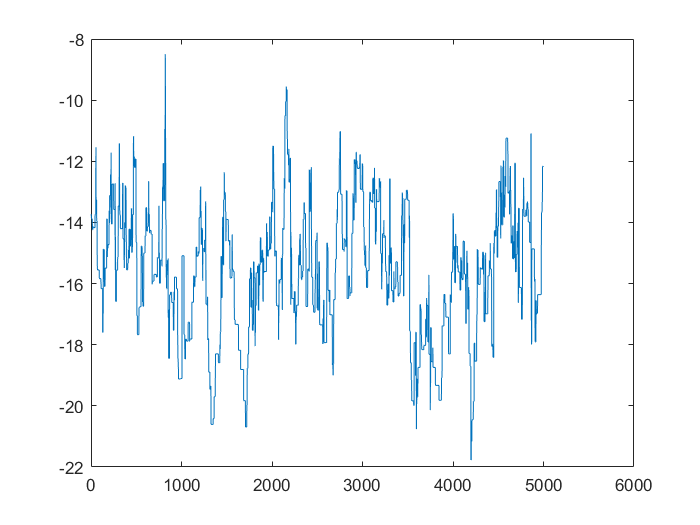

figure(2); 
plot(U_hist); 